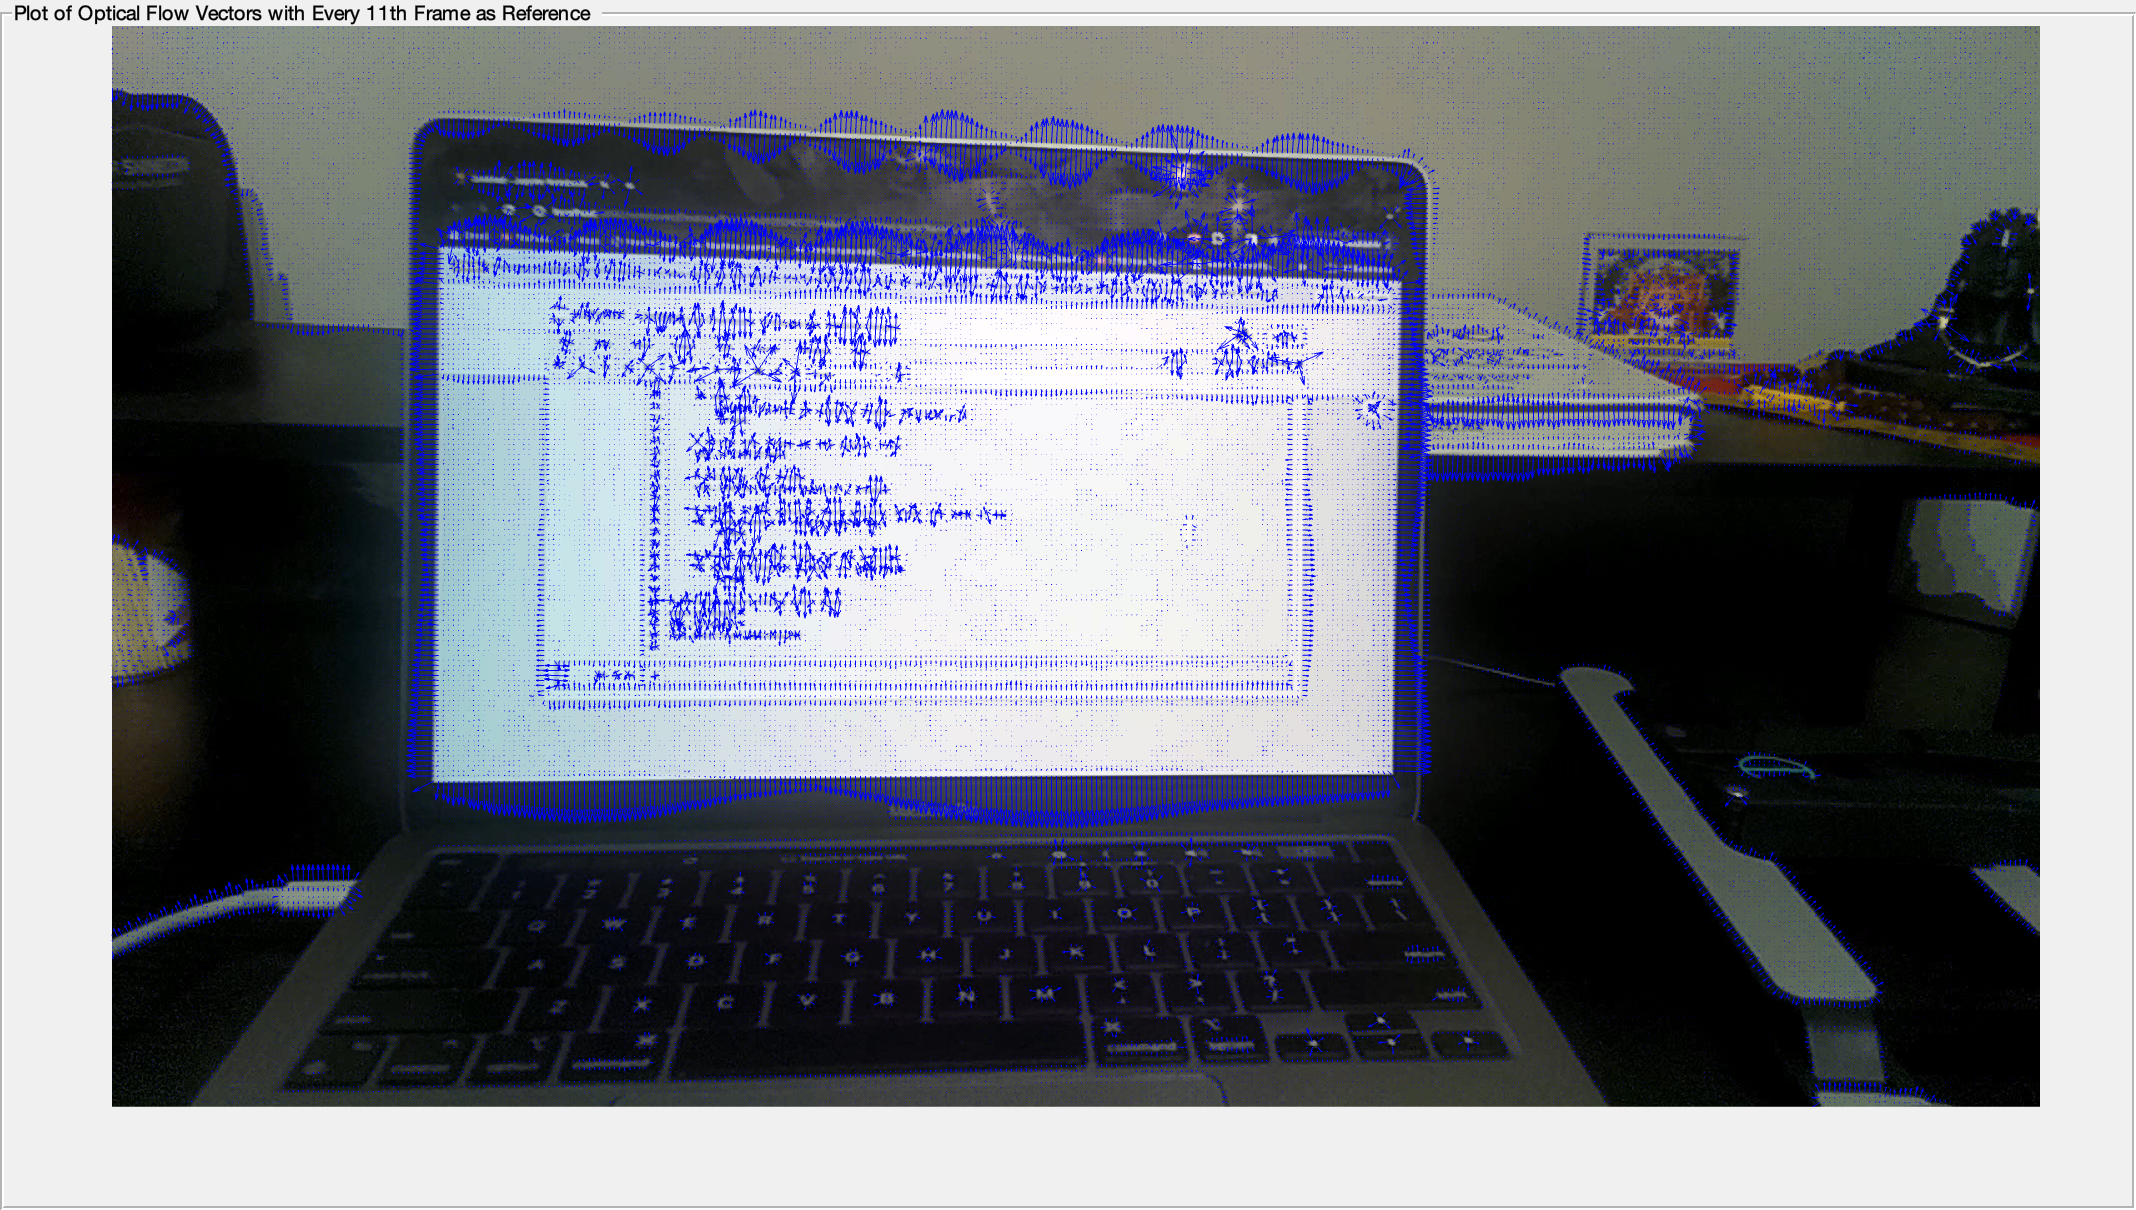

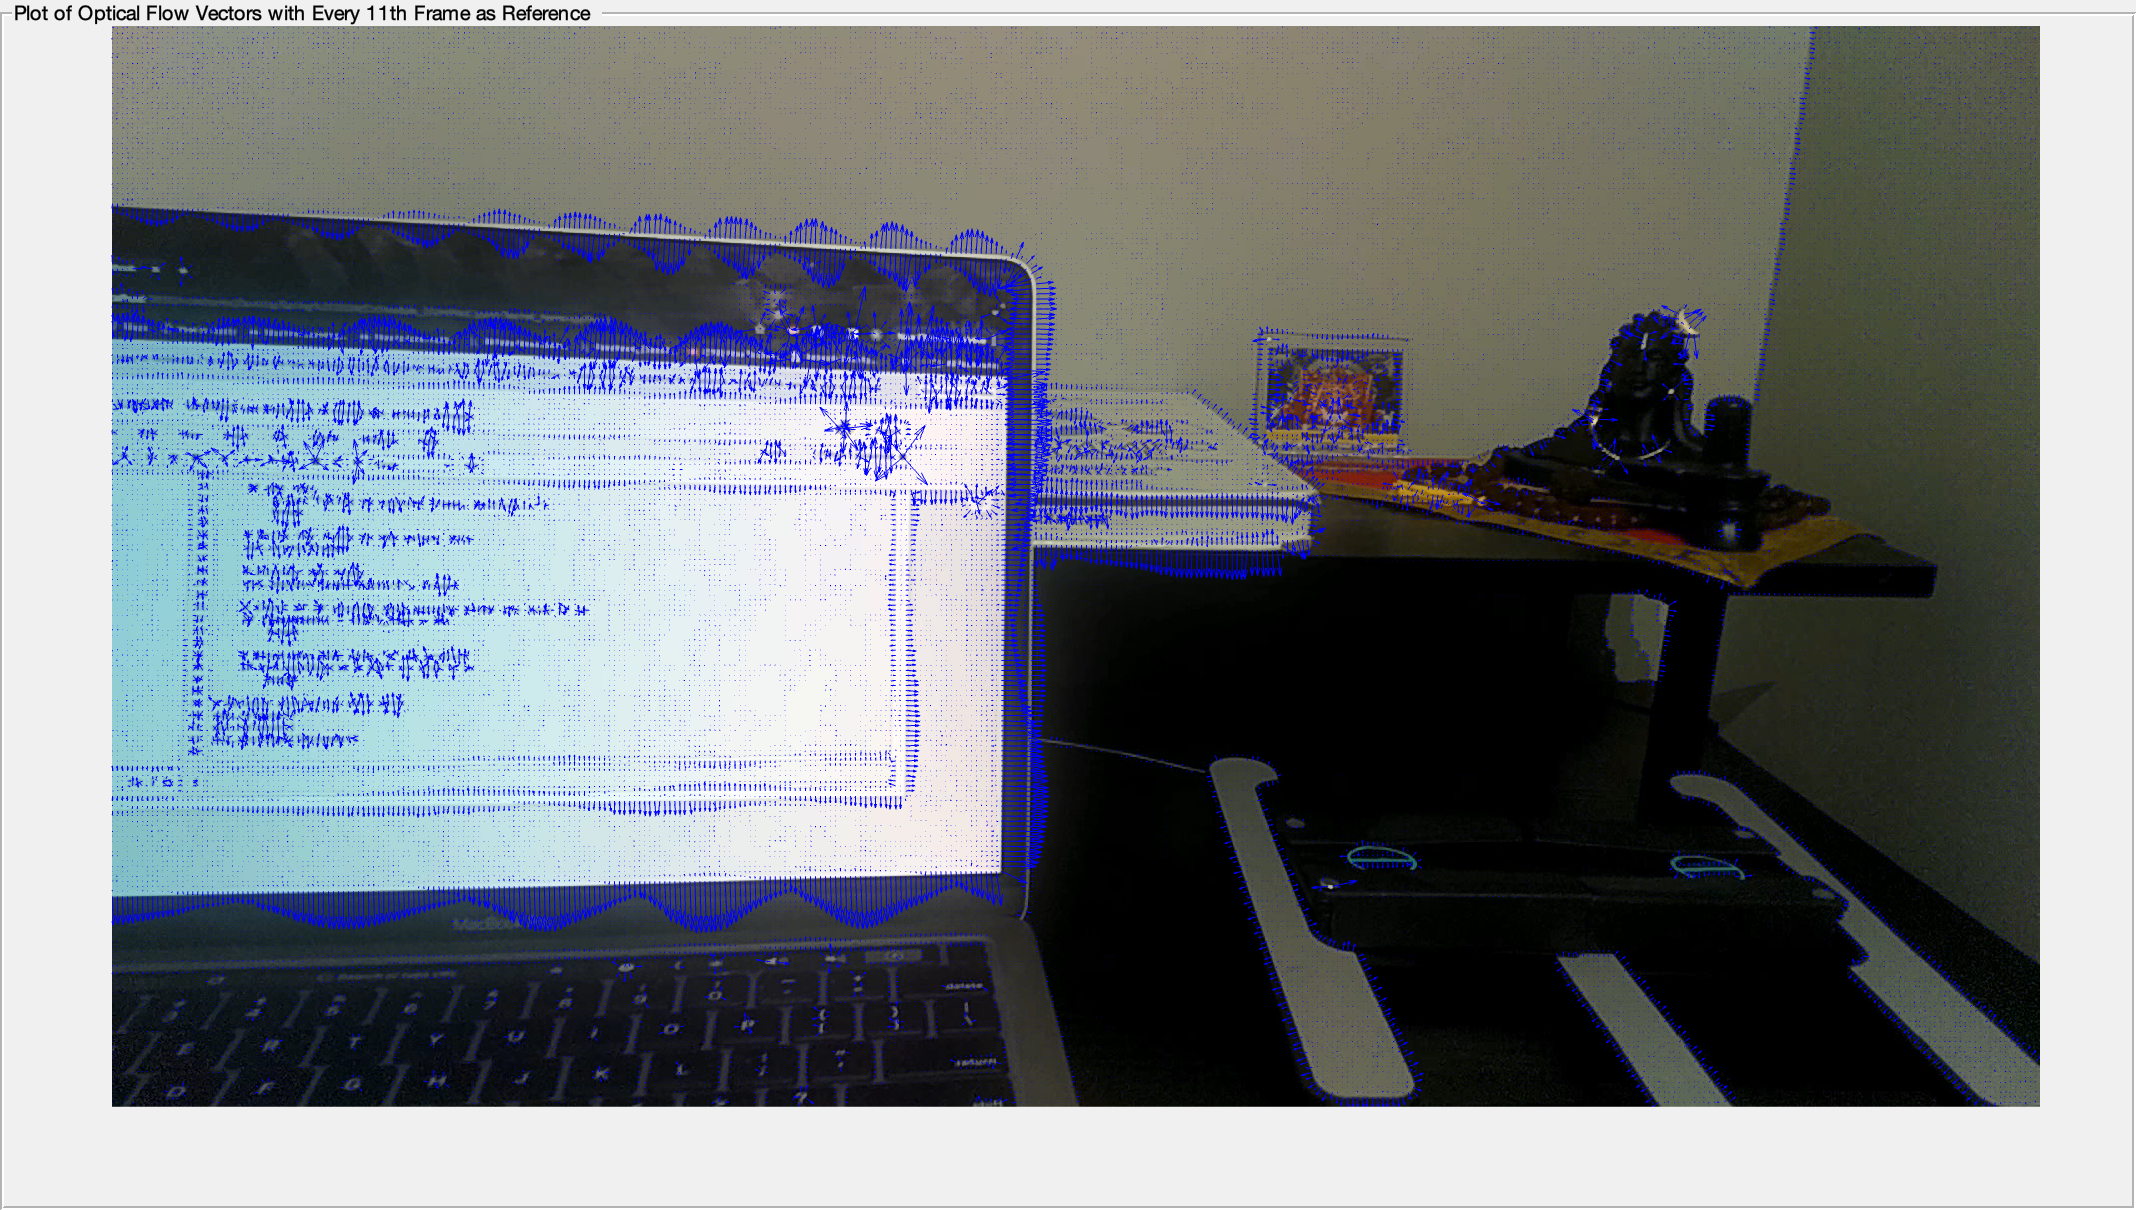

vidReader = VideoReader('output.mp4', 'CurrentTime', 1);
opticFlow = opticalFlowHS;

h = figure;
movegui(h);
hViewPanel = uipanel(h, 'Position', [0 0 1 1], 'Title', 'Plot of Optical Flow Vectors with Every 11th Frame as Reference');
hPlot = axes(hViewPanel);

frameCount = 0; % Initialize frame counter

while hasFrame(vidReader)
    frameRGB = readFrame(vidReader);
    frameGray = im2gray(frameRGB);  
    frameCount = frameCount + 1;
    
    % Reset optical flow estimation every 11th frame
    if mod(frameCount, 11) == 0
        opticFlow = opticalFlowHS; % Re-initialize the optical flow object
    else
        flow = estimateFlow(opticFlow, frameGray);
    end
    
    imshow(frameRGB);
    
    hold on;
    plot(flow, 'DecimationFactor', [5 5], 'ScaleFactor', 60, 'Parent', hPlot);
    hold off;
    pause(10^-1);
end